# Modello dinamico di SPONG Robot SCARA

## Parametri

n_stati = 8; n_input = 4; n_output = 4;
s = tf('s');

J_m1 = 1.5e-3; J_c1 = 8e-1;
J_m2 = 1e-3; J_c2 = 3e-2;
k_1 = 1000; h_1 = .05; h_m1 = .02;
k_2 = 800; h_2 = .02; h_m2 = .01;

## Modello di SPONG

Il modello completo prevede **8 stati**: $x=\left\lbrack \alpha_{m_1 } ,\alpha_{c_1 } ,\alpha_{m_2 } ,\alpha_{c_2 } ,\dot{\alpha_{m_1 } } ,\dot{\alpha_{c_1 } } ,\dot{\alpha_{m_2 } } ,\dot{\alpha_{c_2 } } \right\rbrack$.

Gli stati sono posizione e velocità di motore e carico di ognuno dei due giunti.

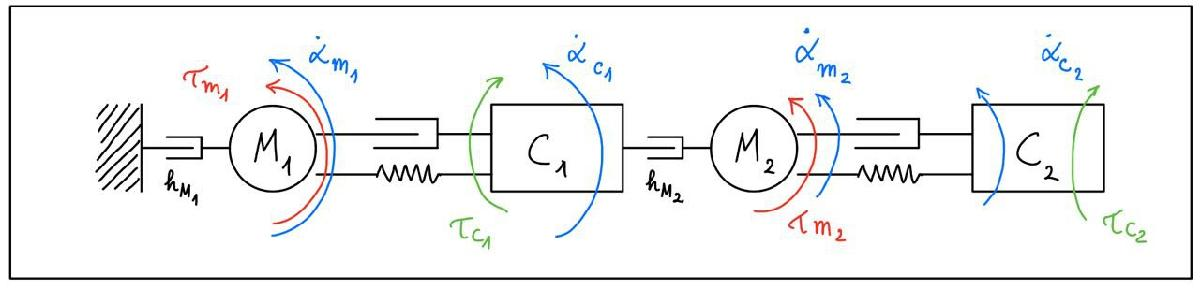

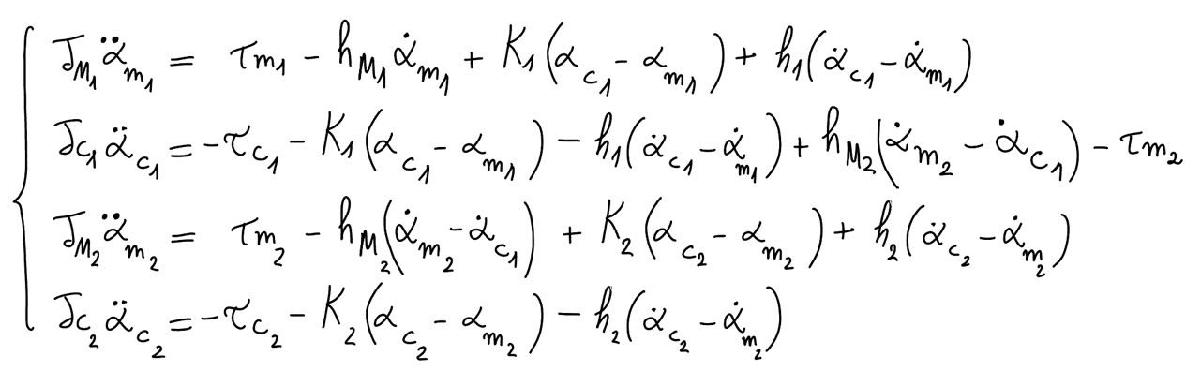

A = zeros(n_stati,n_stati);
A(1,5) = 1; A(2,6) = 1; A(3,7) = 1; A(4,8) = 1;
A(5,:) = J_m1^-1.*[-k_1 k_1 0 0 -(h_m1+h_1) h_1 0 0];
A(6,:) = J_c1^-1.*[k_1 -k_1 0 0 h_1 -(h_1+h_m2) h_m2 0];
A(7,:) = J_m2^-1.*[0 0 -k_2 k_2 0 h_m2 -(h_m2+h_2) h_2];
A(8,:) = J_c2^-1.*[0 0 k_2 -k_2 0 0 h_2 -h_2];
A

A = 	1.0e+05 *

         0         0         0         0    0.0000         0         0         0
         0         0         0         0         0    0.0000         0         0
         0         0         0         0         0         0    0.0000         0
         0         0         0         0         0         0         0    0.0000
   -6.6667    6.6667         0         0   -0.0005    0.0003         0         0
    0.0125   -0.0125         0         0    0.0000   -0.0000    0.0000         0
         0         0   -8.0000    8.0000         0    0.0001   -0.0003    0.0002
         0         0    0.2667   -0.2667         0         0    0.0000   -0.0000


B = zeros(n_stati,n_input);
B(5,1) = J_m1^-1*1;
B(6,2:3) = J_c1^-1*(-1);
B(7,3) = J_m2^-1*1;
B(8,4) = J_c2^-1*(-1);
B

B = 	1.0e+03 *

         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    0.6667         0         0         0
         0   -0.0013   -0.0013         0
         0         0    1.0000         0
         0         0         0   -0.0333


C = zeros(n_output,n_stati);
C(1,1) = 1; C(2,3) = 1; C(3,5) = 1; C(4,7) = 1;
C

C =      1     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     1     0


D = zeros(n_output,n_input);
D

D =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


states = {'pos_m1' 'pos_c1' 'pos_m2' 'pos_c2' ...
          'vel_m1' 'vel_c1' 'vel_m2' 'vel_c2'};
inputs = {'tau_m1' 'tau_c1' 'tau_m2' 'tau_c2'};
outputs = {'pos_m1' 'pos_m2' 'vel_m1' 'vel_m2'};

sys_ss = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs);

## Conversione nella forma della funzione di trasferimento

sys_tf = zpk(sys_ss)

sys_tf =
 
  From input "tau_m1" to output...
                 666.67 s (s+0.3226) (s^2 + 0.075s + 1250) (s^2 + 30.34s + 8.267e05)
   pos_m1:  -----------------------------------------------------------------------------
            s^2 (s+0.3361) (s+0.02395) (s^2 + 46.7s + 6.679e05) (s^2 + 30.34s + 8.267e05)
 
                            416.67 s (s+2e04) (s^2 + 0.6667s + 2.667e04)
   pos_m2:  -----------------------------------------------------------------------------
            s^2 (s+0.3361) (s+0.02395) (s^2 + 46.7s + 6.679e05) (s^2 + 30.34s + 8.267e05)
 
                666.67 s^2 (s+0.3226) (s^2 + 0.075s + 1250) (s^2 + 30.34s + 8.267e05)
   vel_m1:  -----------------------------------------------------------------------------
            s^2 (s+0.3361) (s+0.02395) (s^2 + 46.7s + 6.679e05) (s^2 + 30.34s + 8.267e05)
 
                           416.67 s^2 (s+2e04) (s^2 + 0.6667s + 2.667e04)
   vel_m2:  -----------------------------------------------------------------------------


Correttamente si ottengono funzioni di trasferimento dell'**8° ordine**.

tf_joint1 = minreal(sys_tf(3,1),1e-3)

tf_joint1 =
 
  From input "tau_m1" to output "vel_m1":
      666.67 (s+0.3226) (s^2 + 0.075s + 1250)
  -----------------------------------------------
  (s+0.3361) (s+0.02395) (s^2 + 46.7s + 6.679e05)
 
Continuous-time zero/pole/gain model.



tf_joint2 = minreal(sys_tf(4,3),1e-3)

tf_joint2 =
 
  From input "tau_m2" to output "vel_m2":
    1000 (s+0.02495) (s^2 + 0.6667s + 2.667e04)
  ------------------------------------------------
  (s+0.3361) (s+0.02395) (s^2 + 30.34s + 8.267e05)
 
Continuous-time zero/pole/gain model.



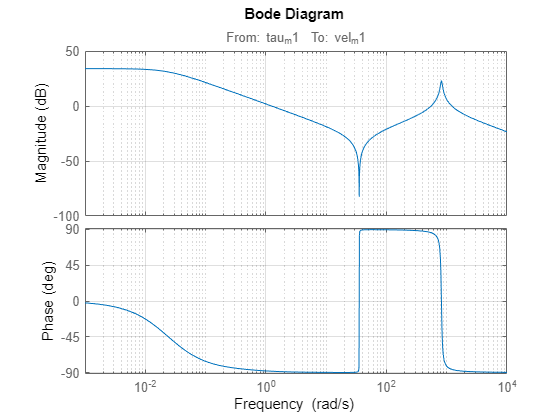

figure; bode(tf_joint1)

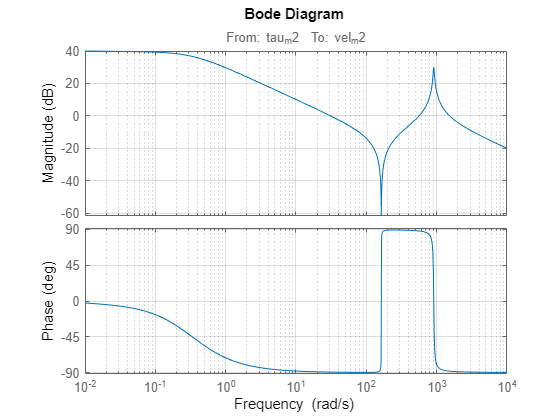

figure; bode(tf_joint2)

## Symbolic

n_stati = 8; n_input = 4; n_output = 4;

syms J_m1 J_c1 J_m2 J_c2 k_1 h_1 h_m1 k_2 h_2 h_m2 s

A = sym(zeros(n_stati,n_stati));
A(1,5) = 1; A(2,6) = 1; A(3,7) = 1; A(4,8) = 1;
A(5,:) = J_m1^-1.*[-k_1 k_1 0 0 -(h_m1+h_1) h_1 0 0];
A(6,:) = J_c1^-1.*[k_1 -k_1 0 0 h_1 -(h_1+h_m2) h_m2 0];
A(7,:) = J_m2^-1.*[0 0 -k_2 k_2 0 h_m2 -(h_m2+h_2) h_2];
A(8,:) = J_c2^-1.*[0 0 k_2 -k_2 0 0 h_2 -h_2];
A

$$A = \left(\begin{array}{cccccccc} 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ -\frac{k_{1}}{J_{\mathrm{m1}}} & \frac{k_{1}}{J_{\mathrm{m1}}} & 0 & 0 & -\frac{h_{1}+h_{\mathrm{m1}}}{J_{\mathrm{m1}}} & \frac{h_{1}}{J_{\mathrm{m1}}} & 0 & 0\\ \frac{k_{1}}{J_{\mathrm{c1}}} & -\frac{k_{1}}{J_{\mathrm{c1}}} & 0 & 0 & \frac{h_{1}}{J_{\mathrm{c1}}} & -\frac{h_{1}+h_{\mathrm{m2}}}{J_{\mathrm{c1}}} & \frac{h_{\mathrm{m2}}}{J_{\mathrm{c1}}} & 0\\ 0 & 0 & -\frac{k_{2}}{J_{\mathrm{m2}}} & \frac{k_{2}}{J_{\mathrm{m2}}} & 0 & \frac{h_{\mathrm{m2}}}{J_{\mathrm{m2}}} & -\frac{h_{2}+h_{\mathrm{m2}}}{J_{\mathrm{m2}}} & \frac{h_{2}}{J_{\mathrm{m2}}}\\ 0 & 0 & \frac{k_{2}}{J_{\mathrm{c2}}} & -\frac{k_{2}}{J_{\mathrm{c2}}} & 0 & 0 & \frac{h_{2}}{J_{\mathrm{c2}}} & -\frac{h_{2}}{J_{\mathrm{c2}}} \end{array}\right)$$

B = sym(zeros(n_stati,n_input));
B(5,1) = J_m1^-1*1;
B(6,2:3) = J_c1^-1*(-1);
B(7,3) = J_m2^-1*1;
B(8,4) = J_c2^-1*(-1);
B

$$B = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \frac{1}{J_{\mathrm{m1}}} & 0 & 0 & 0\\ 0 & -\frac{1}{J_{\mathrm{c1}}} & -\frac{1}{J_{\mathrm{c1}}} & 0\\ 0 & 0 & \frac{1}{J_{\mathrm{m2}}} & 0\\ 0 & 0 & 0 & -\frac{1}{J_{\mathrm{c2}}} \end{array}\right)$$

C = sym(zeros(n_output,n_stati));
C(1,1) = 1; C(2,3) = 1; C(3,5) = 1; C(4,7) = 1;
C

$$C = \left(\begin{array}{cccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 1 & 0 \end{array}\right)$$

D = sym(zeros(n_output,n_input));
D

$$D = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

### Funzioni di trasferimento simboliche

G = simplify(C*inv(s*sym(eye(n_stati))-A)*B+D) %#ok<MINV> 

tf_joint1_sym = collect(G(3,1))

tf_joint2_sym = collect(G(4,3))